file = 'data/satellite_socat_NAACOM.nc';
sss = ncread(file,'sss');
sst = ncread(file,'sst');
chla = ncread(file,'chla');
sla = ncread(file,'sla');
adt = ncread(file,'adt');
fco2 = ncread(file,'fco2_socat');
pco2air = ncread(file,'pco2air');
lon = ncread(file,'lon');
lat = ncread(file,'lat');

year = [1993:2021];
month = [1:12];

fco2(fco2<1) = nan;
sla(sla<-10) = nan;
sss(sss<-10) = nan;
sst(sst<-10) = nan;
chla(chla<0) = nan;
pco2air(pco2air<200) = nan;

fco2(:,181:end,:,:) = nan;
sst(:,181:end,:,:) = nan;
idxseplon = nanmax(find(lon<=-100));
fco2(1:idxseplon,:,:,:) = nan;
fco2(:,1:29,:,:) = nan;

[lat_msh, lon_msh] = meshgrid(lat,lon);
lat_msh = repmat(reshape(lat_msh,[520,220,1,1]),[1,1,12,29]);
lon_msh = repmat(reshape(lon_msh,[520,220,1,1]),[1,1,12,29]);
month_msh = repmat(reshape(month,[1,1,12,1]),[520,220,1,29]);

% highlat
fco2_i = fco2;
sss_i = sss;
sst_i = sst;
chla_i = chla;
sla_i = sla;
adt_i = adt;
pco2air_i = pco2air;
lon_i = lon_msh;
lat_i = lat_msh;
mon_i = month_msh;

fco2_train = nan(size(fco2));
sss_train = nan(size(fco2));
sst_train = nan(size(fco2));
chla_train = nan(size(fco2));
sla_train = nan(size(fco2));
adt_train = nan(size(fco2));
pco2air_train = nan(size(fco2));
lat_train = nan(size(fco2));
lon_train = nan(size(fco2));
mon_train = nan(size(fco2));

fco2_test = nan(size(fco2));
sss_test = nan(size(fco2));
sst_test = nan(size(fco2));
chla_test = nan(size(fco2));
sla_test = nan(size(fco2));
adt_test = nan(size(fco2));
pco2air_test = nan(size(fco2));
lat_test = nan(size(fco2));
lon_test = nan(size(fco2));
mon_test = nan(size(fco2));

idx_test = [2004:2005]-1992;
idx_train = [1993:2021]-1992;
idx_train(idx_test) = [];

fco2_train(:,:,:,idx_train) = fco2_i(:,:,:,idx_train);
sss_train(:,:,:,idx_train) = sss_i(:,:,:,idx_train);
sst_train(:,:,:,idx_train) = sst_i(:,:,:,idx_train);
chla_train(:,:,:,idx_train) = chla_i(:,:,:,idx_train);
sla_train(:,:,:,idx_train) = sla_i(:,:,:,idx_train);
adt_train(:,:,:,idx_train) = adt_i(:,:,:,idx_train);
pco2air_train(:,:,:,idx_train) = pco2air_i(:,:,:,idx_train);
lat_train(:,:,:,idx_train) = lat_msh(:,:,:,idx_train);
lon_train(:,:,:,idx_train) = lon_msh(:,:,:,idx_train);
mon_train(:,:,:,idx_train) = month_msh(:,:,:,idx_train);

fco2_test(:,:,:,idx_test) = fco2_i(:,:,:,idx_test);
sss_test(:,:,:,idx_test) = sss_i(:,:,:,idx_test);
sst_test(:,:,:,idx_test) = sst_i(:,:,:,idx_test);
chla_test(:,:,:,idx_test) = chla_i(:,:,:,idx_test);
sla_test(:,:,:,idx_test) = sla_i(:,:,:,idx_test);
adt_test(:,:,:,idx_test) = adt_i(:,:,:,idx_test);
pco2air_test(:,:,:,idx_test) = pco2air_i(:,:,:,idx_test);
lat_test(:,:,:,idx_test) = lat_msh(:,:,:,idx_test);
lon_test(:,:,:,idx_test) = lon_msh(:,:,:,idx_test);
mon_test(:,:,:,idx_test) = month_msh(:,:,:,idx_test);

idxout_traintrain = nan(size(fco2));
idxout_traintest = nan(size(fco2));
idxout_test = nan(size(fco2));

idxout_traintrain_flat = idxout_traintrain(:);
idxout_traintest_flat = idxout_traintrain(:);
idxout_test_flat = idxout_traintrain(:);

T_train = [lon_train(:),lat_train(:),mon_train(:),sss_train(:),sst_train(:),adt_train(:),pco2air_train(:),fco2_train(:)];
T_test = [lon_test(:),lat_test(:),mon_test(:),sss_test(:),sst_test(:),adt_test(:),pco2air_test(:),fco2_test(:)];

idx_all = [1:size(T_train,1)];
ivalid_train = ~isnan(sum(T_train,2));
idx_all_valid = idx_all(ivalid_train);

T_train_input = T_train(ivalid_train,:);

seed = 100;
rng(seed);

idxtraintest = randperm(size(T_train_input,1),floor(0.2*size(T_train_input,1)));
idxtraintrain = [1:size(T_train_input,1)];
idxtraintrain(idxtraintest) = [];

idx_traintrain = idx_all_valid(idxtraintrain);
idx_traintest = idx_all_valid(idxtraintest);

T_train_train = T_train_input(idxtraintrain,:);
T_train_test = T_train_input(idxtraintest,:);

ivalid_test = ~isnan(sum(T_test,2));
T_test_input = T_test(ivalid_test,:);

idxout_test_flat(ivalid_test) = 1.0;
idxout_validation = reshape(idxout_test_flat,size(idxout_test));

idxout_traintrain_flat(idx_traintrain) = 1.0;
idxout_traintest_flat(idx_traintest) = 1.0;

idxout_train = reshape(idxout_traintrain_flat,size(idxout_test));
idxout_test = reshape(idxout_traintest_flat,size(idxout_test));

T_train_train = T_train(~isnan(idxout_traintrain_flat),:);
T_train_test = T_train(~isnan(idxout_traintest_flat),:);
T_test_input = T_test(~isnan(idxout_test_flat),:);

[trainedModel, validationPredictions, validationRMSE] = trainRFER7(T_train_train);

% Test SSS sensitivity
T_train_test_i = T_train_test;
T_train_test_i(:,4) = T_train_test(:,4)*0.99;
y_test_1 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
T_train_test_i(:,4) = T_train_test(:,4)*1.01;
y_test_2 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
SF_sss = (y_test_2 - y_test_1)./T_train_test(:,4)*0.02;

% Test SST sensitivity
T_train_test_i = T_train_test;
T_train_test_i(:,5) = T_train_test(:,5)*0.99;
y_test_1 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
T_train_test_i(:,4) = T_train_test(:,5)*1.01;
y_test_2 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
SF_sst = (y_test_2 - y_test_1)./T_train_test(:,5)*0.02;

% Test SST sensitivity
T_train_test_i = T_train_test;
T_train_test_i(:,5) = T_train_test(:,5)*0.99;
y_test_1 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
T_train_test_i(:,4) = T_train_test(:,5)*1.01;
y_test_2 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
SF_sst = (y_test_2 - y_test_1)./T_train_test(:,5)*0.02;

% Test SST sensitivity
T_train_test_i = T_train_test;
T_train_test_i(:,5) = T_train_test(:,5)*0.99;
y_test_1 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
T_train_test_i(:,4) = T_train_test(:,5)*1.01;
y_test_2 = trainedModel.predictFcn(T_train_test_i(:,1:end-1));
SF_sst = (y_test_2 - y_test_1)./T_train_test(:,5)*0.02;


y_validation = trainedModel.predictFcn(T_test_input(:,1:end-1));

T_all = [lon_msh(:),lat_msh(:),month_msh(:),sss(:),sst(:),adt(:),pco2air(:)];
ivalid_all = ~isnan(sum(T_all,2));
y_all = trainedModel.predictFcn(T_all(ivalid_all,:));

y_train_withnan = nan(size(T_train,1),1);
y_train_withnan(ivalid_all) = y_all;
y_train_withnan(~isnan(idxout_traintrain_flat)) = validationPredictions;
y_train_withnan(~isnan(idxout_traintest_flat)) = y_test;
y_train_withnan(~isnan(idxout_test_flat)) = y_validation;


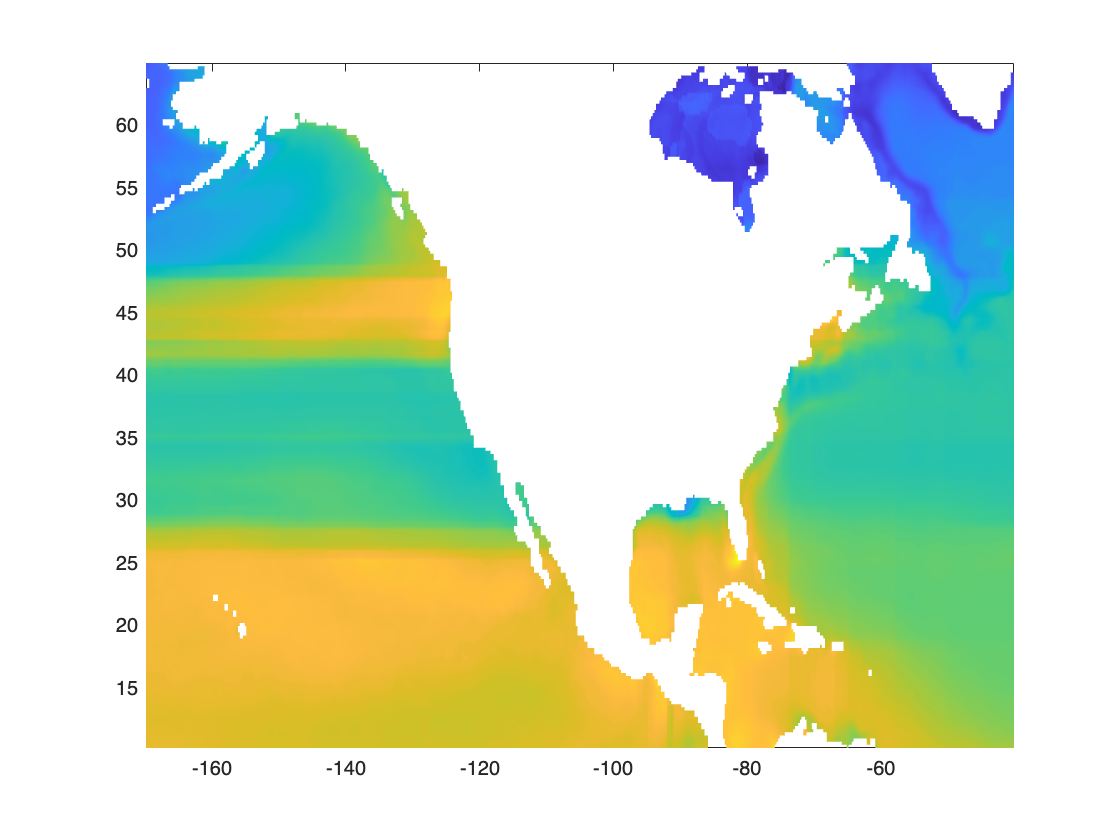

fco2_est_4d = reshape(y_train_withnan,size(idxout_test));

pcolor(lon,lat,nanmean(nanmean(fco2_est_4d,4),3)');
% clim([350,500]);
% m_grid();
shading interp

save('data/fco2_est_4d.mat','fco2_est_4d','idxout_train','idxout_test','idxout_validation','-mat');
